syms alpha1(t) alpha2(t) alpha3(t) Y
syms q [3 1]
syms Lag [3 1]
syms eqns [3 1]

q(1) = alpha1;
q(2) = alpha2;
q(3) = alpha3;
dq = diff(q,t);

m1 = 0.5;
m2 = 0.15;
m3 = 0.05;
l1 = 0.1;
l2 = 0.1;
l3 = 0.1;
g = 9.8;

% REMEBER alpha is the angle with the vertical
x1 = l1*sin(alpha1);
y1 = -l1*cos(alpha1);
x2 = l1*sin(alpha1) + l2*sin(alpha2);
y2 = -l1*cos(alpha1) - l2*cos(alpha2);
x3 = l1*sin(alpha1) + l2*sin(alpha2) + l3*sin(alpha3);
y3 = -l1*cos(alpha1) - l2*cos(alpha2) - l3*cos(alpha3);

T = 0.5*(m1*((diff(x1,t))^2 + (diff(y1,t))^2) + m2*((diff(x2,t))^2 + (diff(y2,t))^2) + m3*((diff(x3,t))^2 + (diff(y3,t))^2));
V = m1*g*y1 + m2*g*y2 + m3*g*y3;
L = T-V;

for i=1:3
    Lag(i) = diff(diff(L,dq(i)),t) - diff(L,q(i)) == 0;
end
for i=1:3
    eqns(i) = simplify(lhs(Lag(i)) - rhs(Lag(i)));
end
eqns == 0 %#ok<EQEFF> 

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{343\,\sin\left(\alpha_{1}\left(t\right)\right)}{500}+\frac{\sin\left(\sigma_{9}\right)\,\sigma_{5}}{500}+\frac{\sin\left(\sigma_{8}\right)\,\sigma_{4}}{2000}+\frac{\cos\left(\sigma_{9}\right)\,\sigma_{2}}{500}+\frac{\cos\left(\sigma_{8}\right)\,\sigma_{1}}{2000}+\frac{7\,\sigma_{3}}{1000}=0\\ \frac{49\,\sin\left(\alpha_{2}\left(t\right)\right)}{250}-\frac{\sin\left(\sigma_{9}\right)\,\sigma_{6}}{500}+\frac{\sin\left(\sigma_{7}\right)\,\sigma_{4}}{2000}+\frac{\cos\left(\sigma_{9}\right)\,\sigma_{3}}{500}+\frac{\cos\left(\sigma_{7}\right)\,\sigma_{1}}{2000}+\frac{\sigma_{2}}{500}=0\\ \frac{49\,\sin\left(\alpha_{3}\left(t\right)\right)}{1000}-\frac{\sin\left(\sigma_{8}\right)\,\sigma_{6}}{2000}-\frac{\sin\left(\sigma_{7}\right)\,\sigma_{5}}{2000}+\frac{\cos\left(\sigma_{8}\right)\,\sigma_{3}}{2000}+\frac{\cos\left(\sigma_{7}\right)\,\sigma_{2}}{2000}+\frac{\sigma_{1}}{2000}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\alpha_{3}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\alpha_{2}\left(t\right)\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\alpha_{1}\left(t\right)\\ \sigma_{4}={\left(\frac{\partial }{\partial t}\alpha_{3}\left(t\right)\right)}^{2}\\ \sigma_{5}={\left(\frac{\partial }{\partial t}\alpha_{2}\left(t\right)\right)}^{2}\\ \sigma_{6}={\left(\frac{\partial }{\partial t}\alpha_{1}\left(t\right)\right)}^{2}\\ \sigma_{7}=\alpha_{2}\left(t\right)-\alpha_{3}\left(t\right)\\ \sigma_{8}=\alpha_{1}\left(t\right)-\alpha_{3}\left(t\right)\\ \sigma_{9}=\alpha_{1}\left(t\right)-\alpha_{2}\left(t\right) \end{array}$$


[VF,Subs] = odeToVectorField(Lag)

$$Subs = \left(\begin{array}{c} \alpha_{2}\\ {\mathrm{Dalpha}}_{2}\\ \alpha_{1}\\ {\mathrm{Dalpha}}_{1}\\ \alpha_{3}\\ {\mathrm{Dalpha}}_{3} \end{array}\right)$$

odefcn = matlabFunction(VF, 'Vars',{t,Y})

odefcn = function_handle with value:
    @(t,Y)[Y(2);((cos(Y(3)).^2.*cos(Y(5)).^2.*sin(Y(1)).*5.096e+3+cos(Y(3)).^2.*sin(Y(1)).*sin(Y(5)).^2.*4.116e+3-cos(Y(1)).*cos(Y(3)).*cos(Y(5)).^2.*sin(Y(3)).*4.116e+3-cos(Y(1)).*cos(Y(3)).^2.*cos(Y(5)).*sin(Y(5)).*9.8e+2-cos(Y(1)).*cos(Y(3)).*sin(Y(3)).*sin(Y(5)).^2.*5.096e+3-cos(Y(1)).*cos(Y(5)).^2.*sin(Y(3)).^3.*Y(4).^2.*4.2e+1+cos(Y(3)).^3.*cos(Y(5)).^2.*sin(Y(1)).*Y(4).^2.*5.2e+1-cos(Y(1)).*cos(Y(3)).^2.*sin(Y(5)).^3.*Y(6).^2.*1.0e+1+cos(Y(3)).^2.*cos(Y(5)).^3.*sin(Y(1)).*Y(6).^2.*1.3e+1-cos(Y(1)).*sin(Y(3)).^3.*sin(Y(5)).^2.*Y(4).^2.*5.2e+1+cos(Y(3)).^3.*sin(Y(1)).*sin(Y(5)).^2.*Y(4).^2.*4.2e+1-cos(Y(1)).*sin(Y(3)).^2.*sin(Y(5)).^3.*Y(6).^2.*1.3e+1+cos(Y(5)).^3.*sin(Y(1)).*sin(Y(3)).^2.*Y(6).^2.*1.0e+1+cos(Y(3)).*cos(Y(5)).*sin(Y(1)).*sin(Y(3)).*sin(Y(5)).*9.8e+2-cos(Y(1)).*cos(Y(3)).*cos(Y(5)).^3.*sin(Y(3)).*Y(6).^2.*3.0-cos(Y(1)).*cos(Y(3)).^3.*cos(Y(5)).*sin(Y(5)).*Y(4).^2.*1.0e+1+cos(Y(3)).*sin(Y(1)).*sin(Y(3)).*sin(Y(5)).^3.*Y(6).^2.*3.

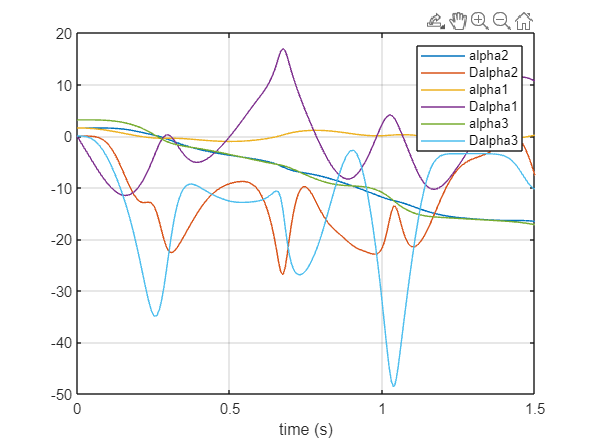

[X,Y] = ode45(odefcn, [0 1.5], [pi/2 0 pi/2 0 pi 0]);

plot(X, Y)
xlabel('time (s)')
grid
legend(string(Subs))

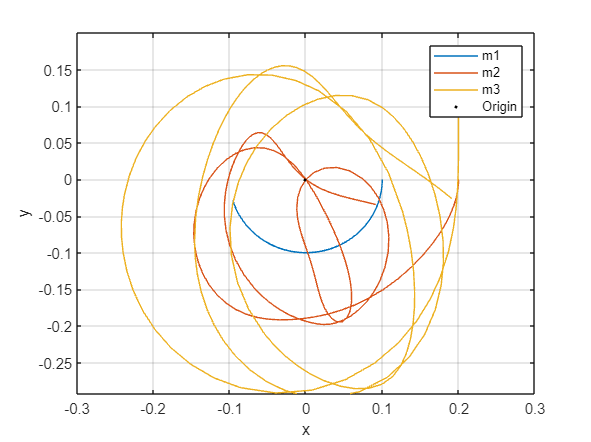


X1 = l1*sin(Y(:,3));
Y1 = -l1*cos(Y(:,3));
X2 = l1*sin(Y(:,3)) + l2*sin(Y(:,1));
Y2 = -l1*cos(Y(:,3)) - l2*cos(Y(:,1));
X3 = l1*sin(Y(:,3)) + l2*sin(Y(:,1)) + l3*sin(Y(:,5));
Y3 = -l1*cos(Y(:,3)) - l2*cos(Y(:,1)) - l3*cos(Y(:,5));

plot(X1,Y1,'DisplayName','m1')
grid
hold on
plot(X2,Y2,'DisplayName','m2')
plot(X3,Y3,'DisplayName','m3')
legend
xlabel('x')
ylabel('y')
plot(0,0,'.k','DisplayName','Origin')
hold off


% %ANIMATION
% figure
% hold on
% grid minor 
% axis equal
% % Plotting with no color to set axis limits
% plot(X1,Y1,'Color','none');
% plot(X2,Y2,'Color','none');
% plot(X3,Y3,'Color','none');
% % Plotting the first iteration
% plot(0,0,'ko')
% p1 = plot(X1(1),Y1(1),'b');
% m1 = scatter(X1(1),Y1(1),'filled','b');
% l1 = plot([0 X1(1)],[0 Y1(1)],'k-');
% p2 = plot(X2(1),Y2(1),'r');
% m2 = scatter(X2(1),Y2(1),'filled','r');
% l2 = plot([X1(1) X2(1)],[Y1(1) Y2(1)],'k-');
% p3 = plot(X3(1),Y3(1),'g');
% m3 = scatter(X3(1),Y3(1),'filled','g');
% l3 = plot([X2(1) X3(1)],[Y2(1) Y3(1)],'k-');
% % Iterating through the length of the time array
% for k = 1:length(Y(:,1))
%     % Updating the line
%     p1.XData = X1(1:k);
%     p1.YData = Y1(1:k);
%     p2.XData = X2(1:k);
%     p2.YData = Y2(1:k);
%     p3.XData = X3(1:k);
%     p3.YData = Y3(1:k);
%     % Updating the point
%     m1.XData = X1(k); 
%     m1.YData = Y1(k);
%     m2.XData = X2(k); 
%     m2.YData = Y2(k);
%     m3.XData = X3(k); 
%     m3.YData = Y3(k);
%     l1.XData = [0 X1(k)];
%     l1.YData = [0 Y1(k)];
%     l2.XData = [X1(k) X2(k)];
%     l2.YData = [Y1(k) Y2(k)];
%     l3.XData = [X2(k) X3(k)];
%     l3.YData = [Y2(k) Y3(k)];
%     % Delay
%     pause(0.05)
% end
